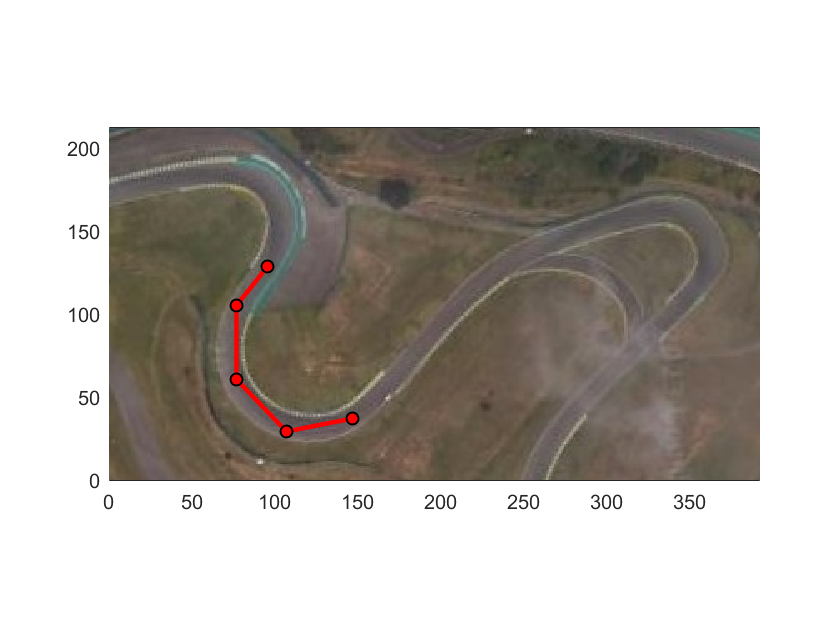

% Lake Etsitty, MENG 451 project

% INSTRUCTIONS
% Step 1) make sure you have "bsplinewaypoints.mlx" ready to be called
% Step 2) Run this script, select your points, see the graphs
% Step 3) Run "angle_change_per_point.mlx" ; this is the only relevant file
% that you'll need to understand my final process. 

% NOTE: 
t = 1; y = t;
plot(t,y); 
hold on; 
grid on
% Loading the image
FG = imread('C:\Users\dcets\Pictures\interlagos2.jpg');
[height, width, colour_planes] = size(FG);

% Gotta flip the image
FG = flipud(FG);

% Insert the image onto the plot, fitting into a specifiec rectangle
% Ih this case, we are using the image's dimensions so as not to
% distort the image.
image(FG,'xdata',[0 width],'ydata',[0 height])

% Plot formatting
axis equal
xlim([0 width])
ylim([0 height])

% The brains of the point-selection operation
[xi,yi] = getpts;
Pos = [xi yi];
roi = drawpolyline('Position', Pos,"InteractionsAllowed","all",'Colo','r');

h.LineWidth = 1;

% Creating variables for the waypoints
wpts1 = xi;
wpts2 = yi;

wpts = [xi' ; yi'];
% Specifying the smoothness; aka how many points 
% do you want along your splines
smooth = 0.01;

% Calling the function
[q, qd, qdd, cpts,pp ] = bsplinewaypoints(wpts,smooth);

figure % Delete this line if you want the spline on the image itself

% Plotting the b-splines
hold all
plot(wpts1, wpts2, 'o')
plot(cpts(1,:), cpts(2,:), 'x-')
plot(q(1,1),q(2,1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')
plot(q(1,1:end), q(2,1:end),'o-','Color',[0.4940, 0.1840, 0.5560])

plot(q(1,0.2/smooth),q(2,0.2/smooth),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(q(1,0.4/smooth),q(2,0.4/smooth),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(q(1,0.5/smooth),q(2,0.5/smooth),'o','linewidth',2,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(q(1,0.6/smooth),q(2,0.6/smooth),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(q(1,0.8/smooth),q(2,0.8/smooth),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')

title('Position')
axis equal
legend('Path Points', 'Computed control polygon','Start','B-spline')

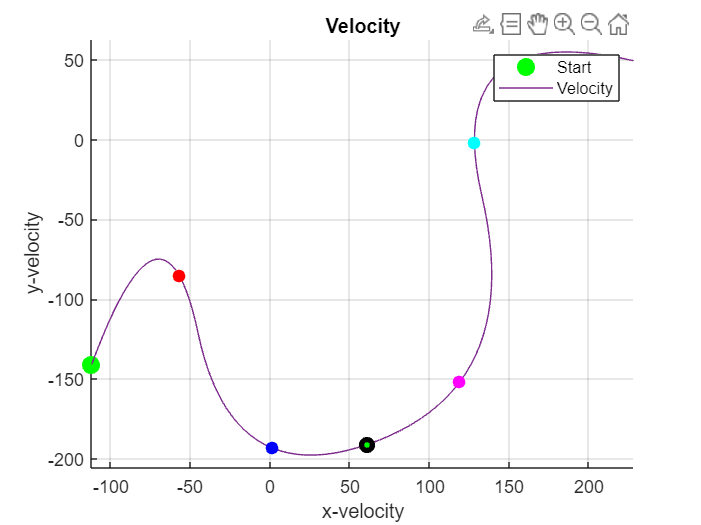


% ------ ALL CODE AFTER THIS LINE IS IRRELEVANT --------
% I wanted to see the velocity and the acceleration
% plots, just in case they were useful 

figure
hold all
plot(qd(1,1),qd(2,1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')
plot(qd(1,1:end-1),qd(2,1:end-1),'-','Color',[0.4940, 0.1840, 0.5560])

plot(qd(1,0.2/smooth),qd(2,0.2/smooth),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(qd(1,0.4/smooth),qd(2,0.4/smooth),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(qd(1,0.5/smooth),qd(2,0.5/smooth),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(qd(1,0.6/smooth),qd(2,0.6/smooth),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(qd(1,0.8/smooth),qd(2,0.8/smooth),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')

title('Velocity')
xlabel('x-velocity')
ylabel('y-velocity')
axis equal
legend('Start','Velocity')
grid on



figure 
hold all
plot(qdd(1,1),qdd(2,1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')
plot(qdd(1,1:end-1), qdd(2,1:end-1),'o-','Color',[0.4940, 0.1840, 0.5560])

plot(qdd(1,0.2/smooth),qdd(2,0.2/smooth),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(qdd(1,0.4/smooth),qdd(2,0.4/smooth),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(qdd(1,0.5/smooth),qdd(2,0.5/smooth),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(qdd(1,0.6/smooth),qdd(2,0.6/smooth),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(qdd(1,0.8/smooth),qdd(2,0.8/smooth),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')

title('Acceleration')
xlabel('x-acceleration')
ylabel('y-acceleration')
axis equal
legend('Start','Acceleration')
grid on